# 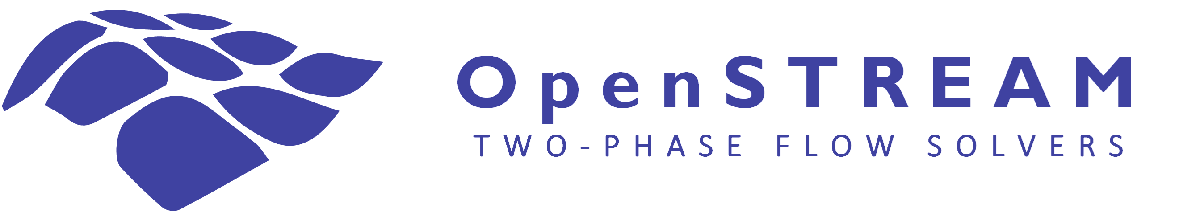

# Tutorial #6: Input files

This tutorial explains how OpenSTREAM input categories are organized, how input sets are selected, and how the same physical-model definition can be read from either the native INP format or JSON.

Learning objectives:

- Identify the four input categories used to assemble an OpenSTREAM case.

- Select an input set by its identifier.

- Inspect imported input objects.

- Load the same model definition from models.inp and models.json.

- Convert a native input file to JSON using the OpenSTREAM input utility.

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up OpenSTREAM

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

Import the Inputs package. No Solvers package is used in this tutorial.

import Inputs.*

## Input organization

An OpenSTREAM case is assembled from four input categories. Each category is normally stored in a dedicated file:

- models.inp contains physical-model and closure-model selections.

- options.inp contains numerical options.

- geom.inp contains geometry definitions.

- A case-specific boundary-condition file contains the operating conditions and power distributions.

A file may contain several input sets. The selected set is identified by an ID such as TUTORIAL1 or DEFAULT. This organization allows physical models, numerical options, geometries, and boundary conditions to be combined and reused without duplicating complete case definitions.

To obtain the full path of the input files (in native format) contained in the OpenSTREAM inputs folder, use the following commands:

modelInpPath = fullfile(osp,'inputs','models.inp');
modelJsonPath = fullfile(osp,'inputs','models.json');
optionsPath = fullfile(osp,'inputs','options.inp');
geometryPath = fullfile(osp,'inputs','geom.inp');
bcPath = fullfile(osp,'inputs','tutorial1.inp');

## Inspect the native input files

Display the supplied native input files. The models file contains several model sets, while the other files provide the numerical options, geometry, and boundary conditions used to assemble the reference case.

type(modelInpPath)
type(optionsPath)
type(geometryPath)
type(bcPath)

## Assemble a reference case from native INP files

Construct an InputSet using the TUTORIAL1 model and geometry, the DEFAULT numerical options, and the Tutorial 1 boundary conditions.

% Construct the input set from the native INP files.
inputSetInp = InputSet( ...
    modelFilePath    = modelInpPath, ...
    modelID          = 'TUTORIAL1', ...
    optionsFilePath  = optionsPath, ...
    optionsID        = 'DEFAULT', ...
    geometryFilePath = geometryPath, ...
    geometryID       = 'TUTORIAL1', ...
    bcFilePath       = bcPath, ...
    LOGMODE          = 'LOGTOCONSOLEONLY');

A warning lists all input parameters that are not specified in the selected input files. The corresponding properties retain the default values defined by their input classes.

Inspect the imported input objects.

disp(inputSetInp.model)
disp(inputSetInp.options)
disp(inputSetInp.geometry)
disp(inputSetInp.bc)

The imported input objects contain the complete set of available input parameters. Depending on the selected solver and active models, however, some parameters may not be used in the calculation.

## Assemble the same case using models.json

The JSON model file is stored in the same inputs folder as models.inp and is named models.json. Only the physical-model file is changed here. The numerical options, geometry, and boundary-condition files remain the same.

% Construct the equivalent input set using models.json.
inputSetJson = InputSet( ...
    modelFilePath    = modelJsonPath, ...
    modelID          = 'TUTORIAL1', ...
    optionsFilePath  = optionsPath, ...
    optionsID        = 'DEFAULT', ...
    geometryFilePath = geometryPath, ...
    geometryID       = 'TUTORIAL1', ...
    bcFilePath       = bcPath, ...
    LOGMODE          = 'LOGTOCONSOLEONLY');
disp(inputSetJson.model)

The model parameters imported from the JSON file are identical to those imported from the native .inp file, including values retained from the model-class defaults. The choice of INP or JSON changes the representation of the input data, not the resulting OpenSTREAM model object.

## Convert a native input file to JSON

Inputs.Input.convert2JSON reads a supported OpenSTREAM input file and returns pretty-printed JSON text. The example writes the converted file to the current directory so that the repository inputs are not modified.

jsonText = Inputs.Input.convert2JSON(modelInpPath);
jsonFile = 'models_converted.json';
if isfile(jsonFile), delete(jsonFile); end

fileId = fopen(jsonFile,'w');
fprintf(fileId,'%s',jsonText);
fclose(fileId);

type(jsonFile)

## Summary

In this tutorial, you assembled an OpenSTREAM case from separate input categories, selected reusable input sets by ID, loaded a physical-model set from both models.inp and models.json, and converted the native model file to JSON.